## 1. 加载数据

load Paras.mat
load Octane.mat

## 2. 调用SP的构造函数，生成SP类的一个对象

此时生成的对象仅仅完成基本的参数初始化，并不调用任何内置方法

函数原型：`obj`` = ``SP``(``methodlist``, ``specdata``, ``methodclass``, ``samplemode``, ``times``)，此处的methodlist为一个结构体类型的方法列表，其中该结构体的每一个元素即为一类预处理方法，然后每一类预处理方法的每一个元素值为一种预处理方法；specdata为表类型的变量，并且该变量包含两列值，一个为光谱矩阵spectra（每行对应一个样本，每列对应一个波长），另外一个为待分析对象的属性值y；methodclass为一个字符串数组，例如：["df","ct"])；samplemode为一个字符串变量，例如："Rand"、"KS"、"SPXY"或者"Rank"，他们分别为“随机抽样”、“KS抽样”、“SPXY抽样”和自定义的“排序抽样”`

sp = SP(MethodList,Data, ["df","ct"])

sp =   SP - 属性:

          CalibrationModel: [1×1 PLSR]
            SamplingMethod: "Rand"
             SamplingRatio: []
               MethodClass: ["df"    "ct"]
                MethodList: [1×1 struct]
                      Data: [60×2 table]
         MethodCombination: []
            PerformanceSta: []
                  ModelSta: []
           PerformanceSta2: []
                 ModelSta2: []
     OptimalProcessingName: []
    OptimalProcessingIndex: []
             OptimalResult: []


## 3. 生成所有可能的预处理方案

调用方法getMethodCombination（）后，将会返回预处理方案，同时将返回的参数设置sp对象的属性`MethodCombination`

`函数原型：AllScheme`` = ``getMethodCombination``(``obj``)，该方法不需要输入参数，返回参数全部`预处理方案`AllScheme。`

sp.getMethodCombination

ans = 63×2 table
     Var1       Var2   
    ______    _________

    ""        <missing>
    "ct1"     <missing>
    "ct2"     <missing>
    "df1"     <missing>
    "df2"     <missing>
    "df3"     <missing>
    "df4"     <missing>
    "df5"     <missing>
    "df6"     <missing>
    "df7"     <missing>
    "df8"     <missing>
    "df9"     <missing>
    "df10"    <missing>
    "df11"    <missing>
    "df12"    <missing>
    "ct1"     "df1"    


## 4. 根据生成的预处理方案计算每种方案对应的模型性能

调用方法getPerformance（）后，将会返回两个M×N的矩阵，一个为全部的模型性能`PF（该值将自动为SP对象属性PerformanceSta赋值）`，一个为所有的模型参数`MD（该值将自动为SP对象属性ModelSta赋值）`。M为独立运行的次数，该参数由SP对象属性`RunTimes决定；N为所有预处理方法方案的个数，即MethodCombination的长度。模型性能包括RMSECV、RMSEC、RMSEV、LV、RC2、RV2`

`函数原型：[PF, MD] = getPerformance(obj)，该方法不需要输入参数，返回模型性能PF和模型MD。计算模型性能时，样本的划分策略是这样的：按照SP初始化参数时samplemode的类型而定。`

sp.getPerformance("rand", 10)


------>>>>>>>>>The 1th iteration has been completed<<<<<<------
------>>>>>>>>>The 2th iteration has been completed<<<<<<------
------>>>>>>>>>The 3th iteration has been completed<<<<<<------
------>>>>>>>>>The 4th iteration has been completed<<<<<<------
------>>>>>>>>>The 5th iteration has been completed<<<<<<------
------>>>>>>>>>The 6th iteration has been completed<<<<<<------
------>>>>>>>>>The 7th iteration has been completed<<<<<<------
------>>>>>>>>>The 8th iteration has been completed<<<<<<------
------>>>>>>>>>The 9th iteration has been completed<<<<<<------
------>>>>>>>>>The 10th iteration has been completed<<<<<<------
------>>>>>>>>> The PerformanceSta of the 1th group has been extracted<<<<<<------
------>>>>>>>>> The PerformanceSta of the 2th group has been extracted<<<<<<------
------>>>>>>>>> The PerformanceSta of the 3th group has been extracted<<<<<<------
------>>>>>>>>> The PerformanceSta of the 4th group has been extracted<<<<<<------
------>>>>>>>>> The Perfor

ans = 包含以下字段的 struct :
    RMSECV: [10×63 double]
     RMSEC: [10×63 double]
     RMSEV: [10×63 double]
        LV: [10×63 double]
       RC2: [10×63 double]
       RV2: [10×63 double]


绘制全部预处理方案对应的模型性能（结果已按照RMSECV排序）

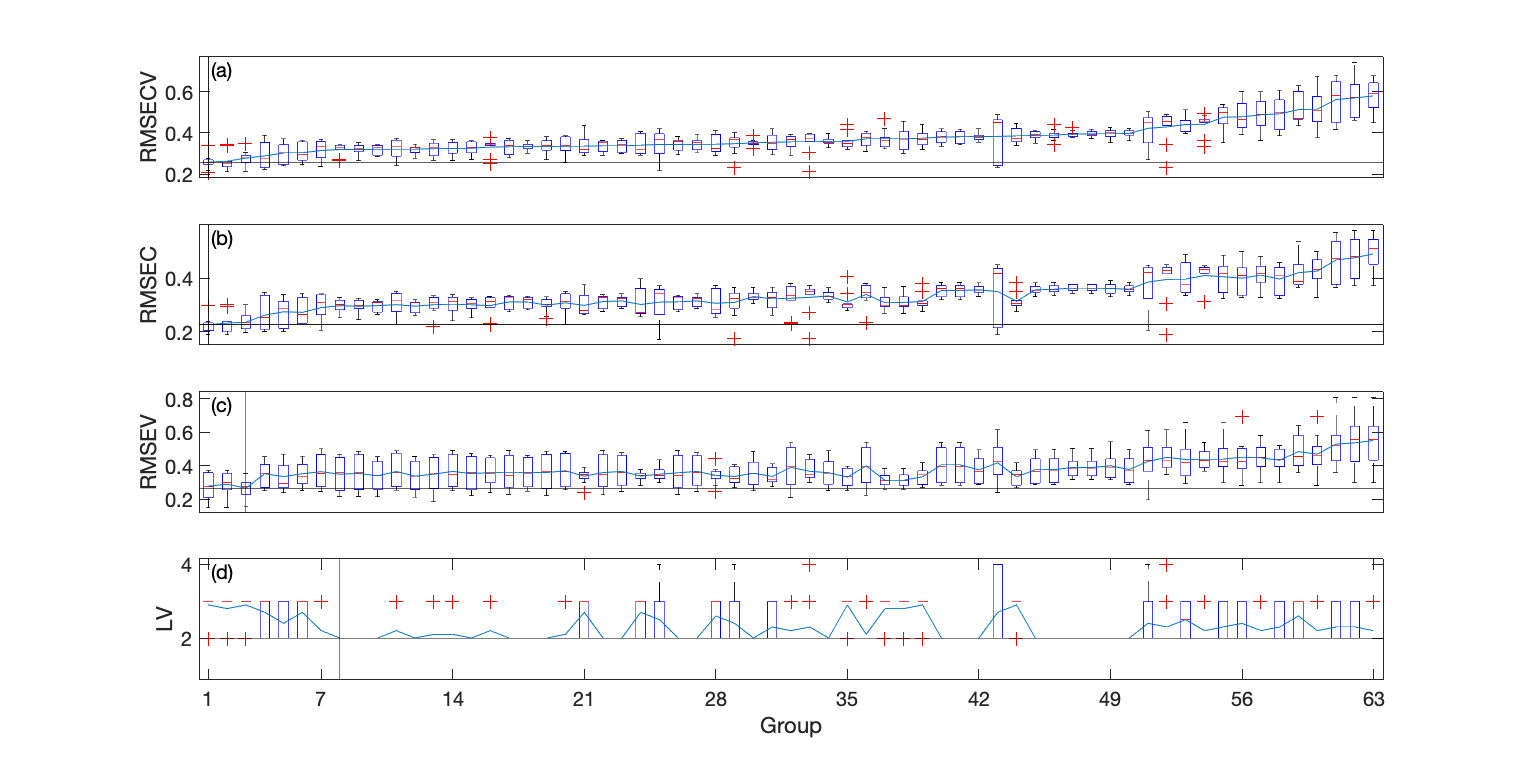

sp.plotAllPerformance(sp.PerformanceSta)

## 5. 根据生成的所有模型性能搜索最优的预处理方法

按照交互验证的结果（RMSECV），返回最优的几种预处理算法。选择的过程为：得到M×N维矩阵RMSECV，然后对其求均值，那么就可以得到每一种预处理方法的平均RMSECV，根据这个均值的大小选择预处理方法。此时还可以查看SP对象中的OptimalProcessingName属性，它展示了当前数据集最优的预处理算法名字

函数原型：`[``OPMID``, ``OPMN``] = ``getOptimalMethod``(``obj``, ``mn``)，其中参数mn为要返回的预处理算法个数，如果全部预处理方案的个数大于10个，那么默认为10个，否则返回RMSECV列的个数个预处理方法`

输出排序后的预处理方法名称

sp.OptimalProcessingName

ans = 63×2 table
    Var1       Var2   
    _____    _________

    "ct1"    <missing>
    "ct2"    <missing>
    ""       <missing>
    "df3"    <missing>
    "df3"    "ct1"    
    "df2"    <missing>
    "df3"    "ct2"    
    "ct1"    "df2"    
    "ct1"    "df3"    
    "ct2"    "df9"    
    "df2"    "ct1"    
    "ct1"    "df9"    
    "df9"    "ct1"    
    "ct2"    "df12"   
    "ct2"    "df2"    
    "df9"    <missing>


## 6. 根据生成的所有模型性能组建最优的校正模型

此处还需要指定抽样方法

函数原型：`[``Result``] = buildModel``(``obj``, ``samplemode``, ``mc``)，此处mc是校正模型，例如PLSR、PCR等`

sp.buildModel("rank",10)


------>>>>>>>>>The 1th iteration has been completed<<<<<<------
------>>>>>>>>>The 2th iteration has been completed<<<<<<------
------>>>>>>>>>The 3th iteration has been completed<<<<<<------
------>>>>>>>>>The 4th iteration has been completed<<<<<<------
------>>>>>>>>>The 5th iteration has been completed<<<<<<------
------>>>>>>>>>The 6th iteration has been completed<<<<<<------
------>>>>>>>>>The 7th iteration has been completed<<<<<<------
------>>>>>>>>>The 8th iteration has been completed<<<<<<------
------>>>>>>>>>The 9th iteration has been completed<<<<<<------
------>>>>>>>>>The 10th iteration has been completed<<<<<<------
------>>>>>>>>> The PerformanceSta of the 1th group has been extracted<<<<<<------
------>>>>>>>>> The PerformanceSta of the 2th group has been extracted<<<<<<------
------>>>>>>>>> The PerformanceSta of the 3th group has been extracted<<<<<<------
------>>>>>>>>> The PerformanceSta of the 4th group has been extracted<<<<<<------
------>>>>>>>>> The Perfor

ans = 10×63 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    

构建模型的性能统计结果（结果已经按照RMSECV排序）

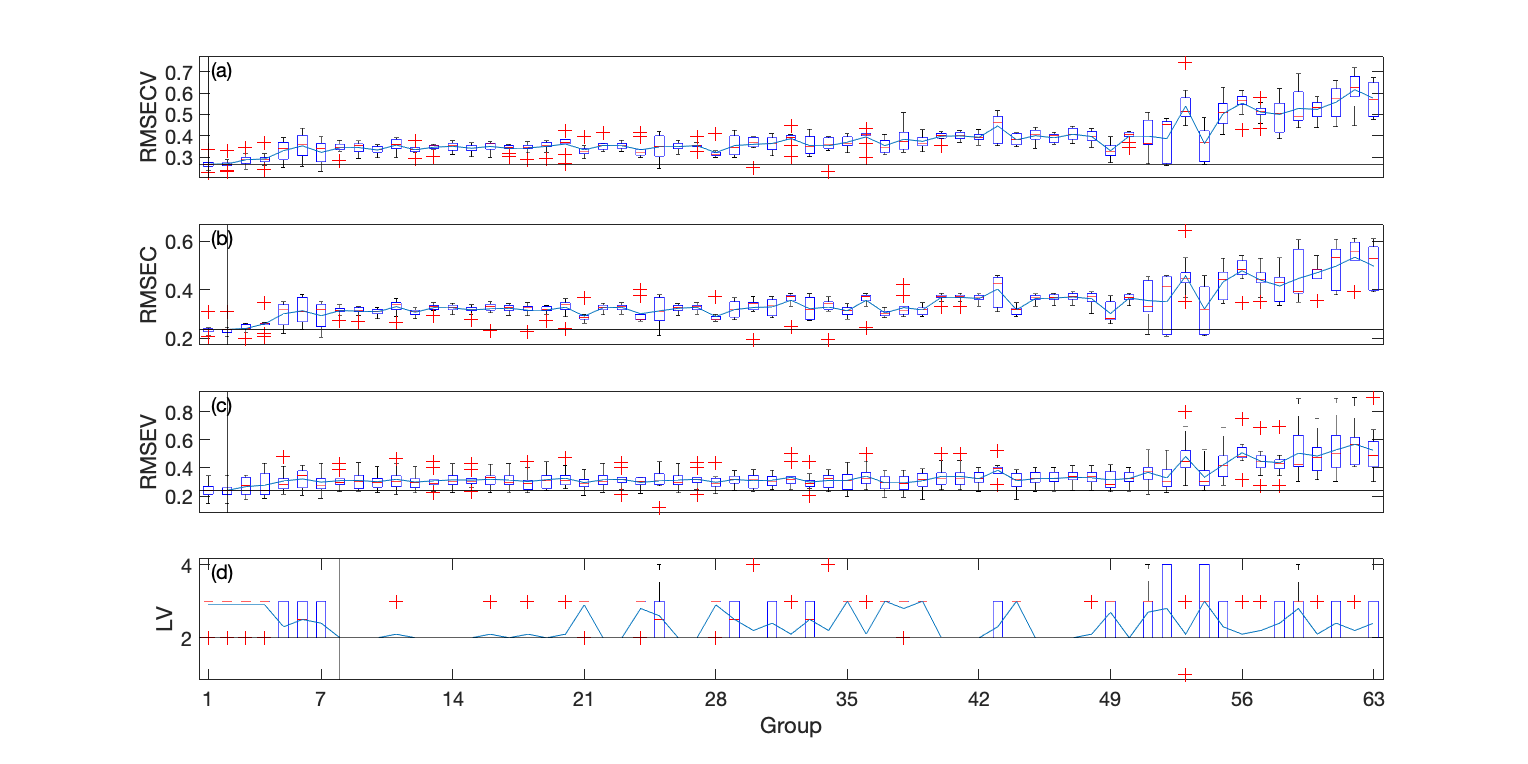

sp.plotAllPerformance(sp.PerformanceSta2)

## 7. 查看相关结果

绘制预处理后的光谱

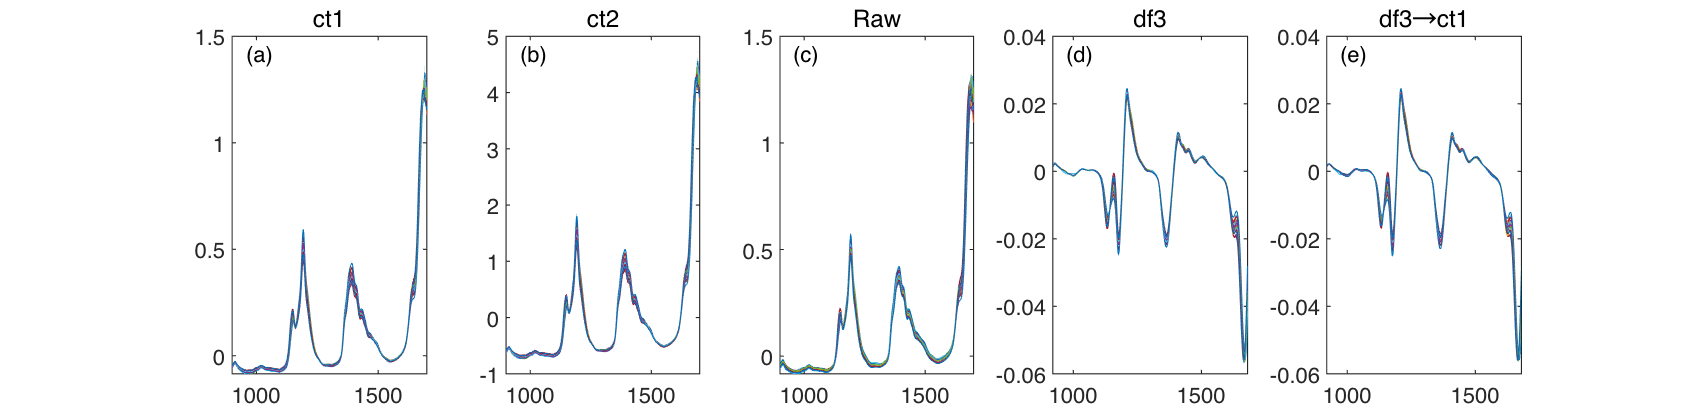

sp.plotProcessedSpec(wavelength,1,[1:5])

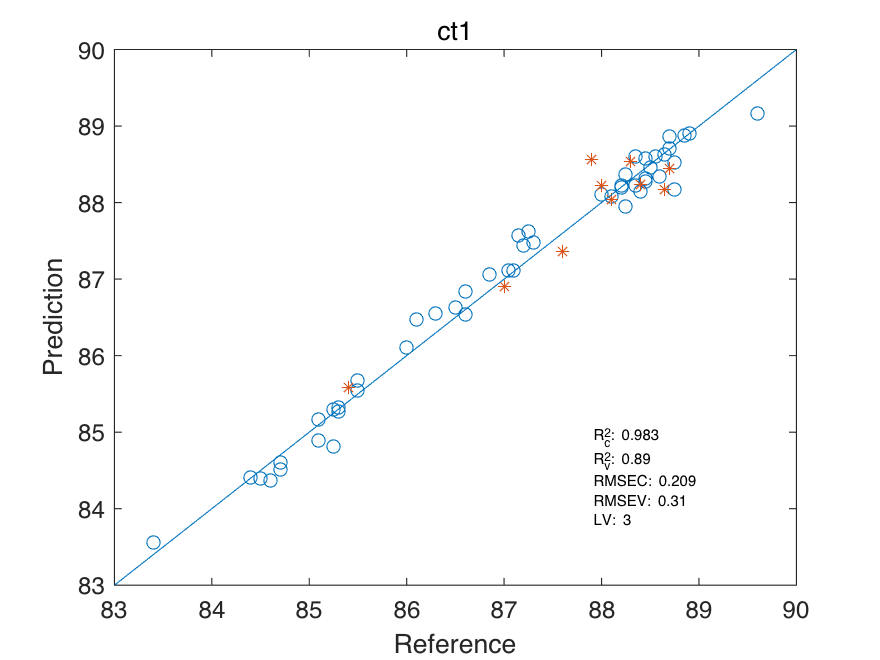

sp.plotModel_RefVSPre(1,1)

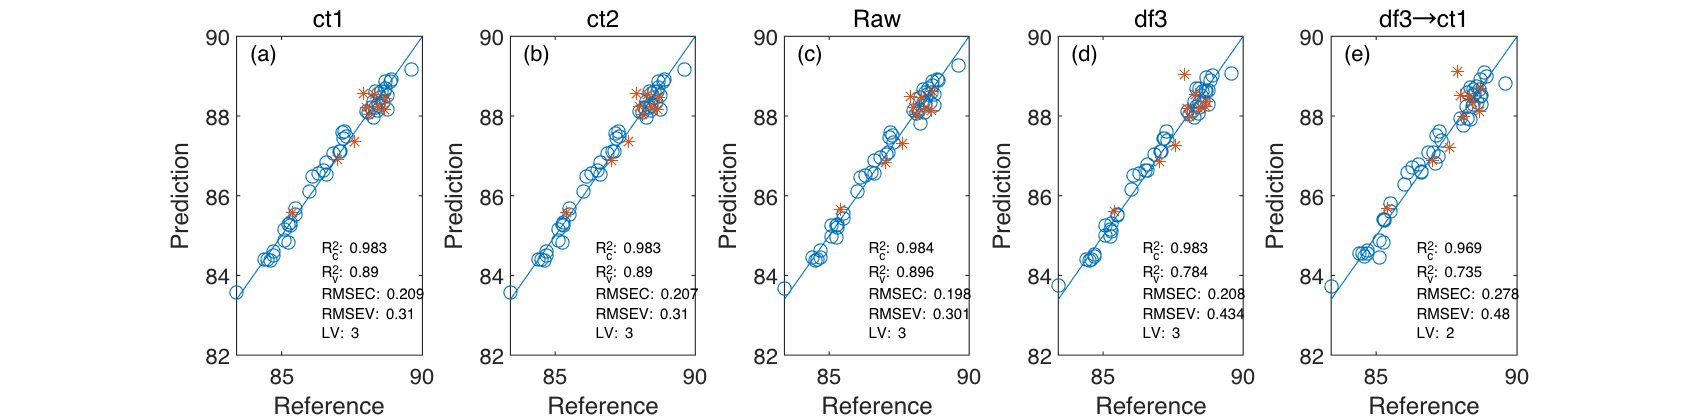

sp.plotModels_RefVSPre(1,[1:5])

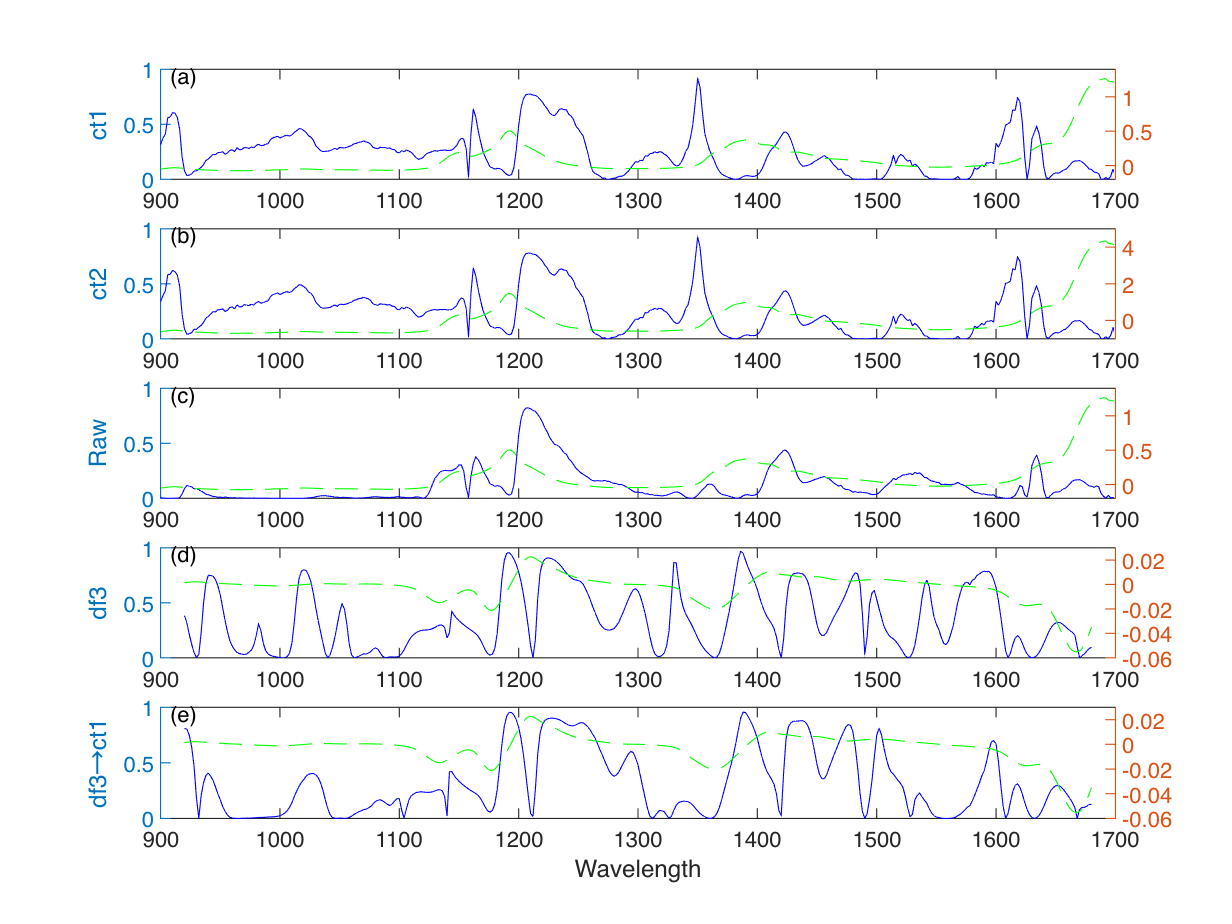

sp.plotR2(1,[1:5], wavelength)

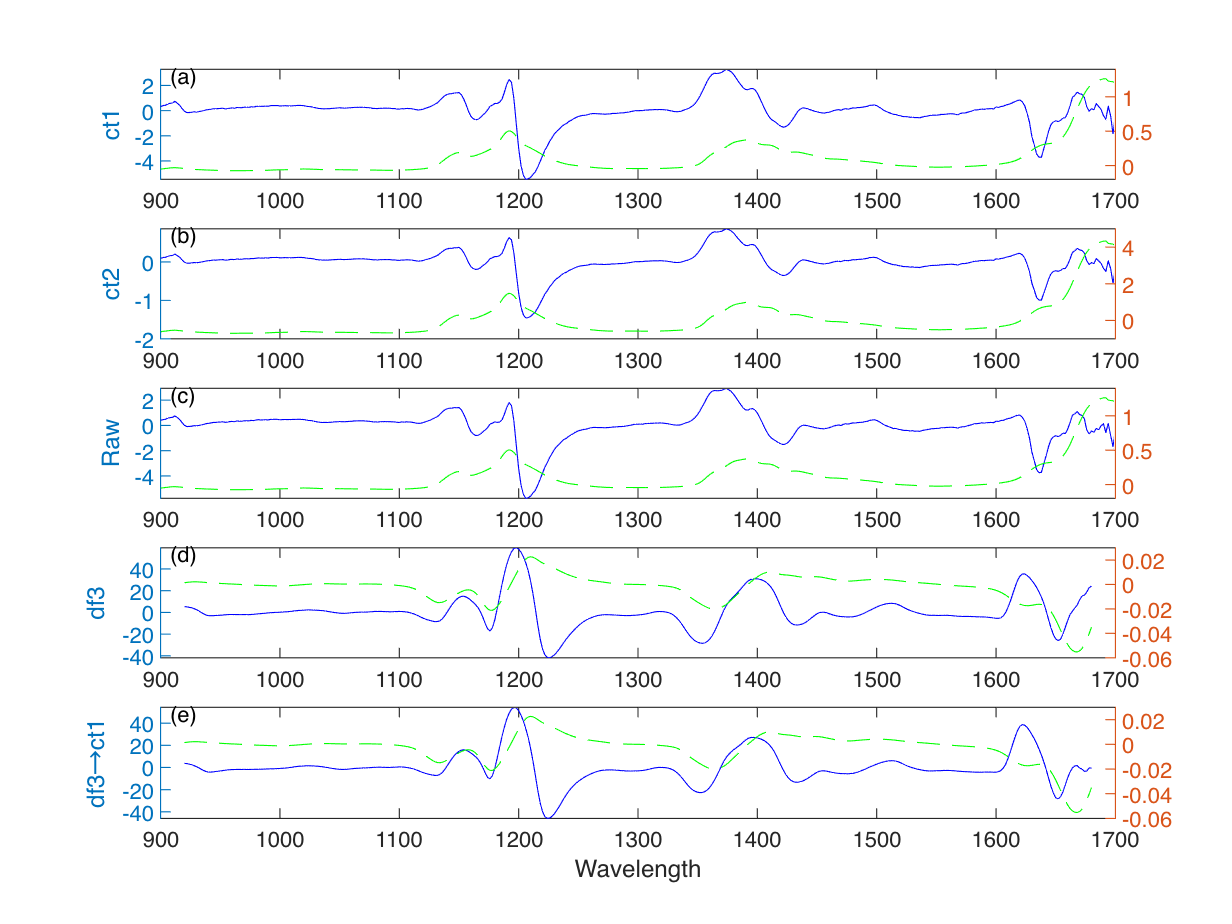

sp.plotplscoe(1,[1:5], wavelength)